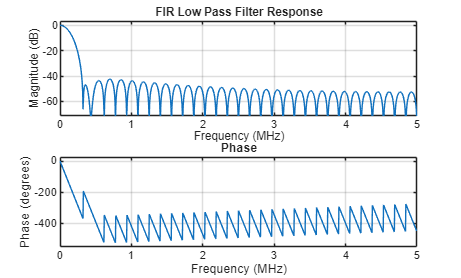

clc;
clear;
close all;

%% ================= PARAMETERS =================
fs = 10e6;        % Sampling frequency (10 MHz)
fc = 2e3;         % Cutoff frequency (2 kHz)
num_taps = 64;    % Number of taps (must match Vivado)

order = num_taps - 1;

%% ================= FIR DESIGN =================
b = fir1(order, fc/(fs/2));   % Low-pass FIR

%% ================= NORMALIZATION =================
% Ensure unity gain at DC
b = b / sum(b);

%% ================= PLOT RESPONSE =================
figure;
freqz(b,1,1024,fs);
title('FIR Low Pass Filter Response');


%% ================= FLOAT COEFFICIENT FILE =================
fid = fopen('fir_coeff_float.txt','w');
for i = 1:length(b)
    fprintf(fid, '%.10f\n', b(i));
end
fclose(fid);

%% ================= FIXED-POINT CONVERSION =================
% Q1.15 format (16-bit signed)
scale = 2^15;

b_fixed = round(b * scale);

% Saturation protection
b_fixed(b_fixed > 32767) = 32767;
b_fixed(b_fixed < -32768) = -32768;

%% ================= SAVE FIXED COEFF (TXT) =================
fid = fopen('fir_coeff_fixed.txt','w');
for i = 1:length(b_fixed)
    fprintf(fid, '%d\n', b_fixed(i));
end
fclose(fid);

%% ================= GENERATE COE FILE (VIVADO) =================
fid = fopen('fir_coeff.coe','w');

fprintf(fid, 'memory_initialization_radix=10;\n');
fprintf(fid, 'memory_initialization_vector=\n');

for i = 1:length(b_fixed)
    if i == length(b_fixed)
        fprintf(fid, '%d;\n', b_fixed(i));
    else
        fprintf(fid, '%d,\n', b_fixed(i));
    end
end

fclose(fid);

%% ================= DISPLAY INFO =================
disp('FIR design completed!');

FIR design completed!


disp('Files generated:');

Files generated:


disp('1. fir_coeff_float.txt  (for reference)');

1. fir_coeff_float.txt  (for reference)


disp('2. fir_coeff_fixed.txt  (for manual use)');

2. fir_coeff_fixed.txt  (for manual use)


disp('3. fir_coeff.coe        (USE THIS IN VIVADO)');

3. fir_coeff.coe        (USE THIS IN VIVADO)


clc;
clear;
close all;

%% Parameters
fs = 10e6;                 % Sampling frequency (10 MHz)
t = 0:1/fs:5e-3;          % Longer time → better averaging
f_ref = 100e3;            % 100 kHz

%% Laser Modulation (Square Wave)
laser_amp = 1;
laser = laser_amp * square(2*pi*f_ref*t);

%% Photodiode + Amplifier Model
gain = 5;
phase_shift = pi/6;       % 30 degrees

signal = gain * square(2*pi*f_ref*t + phase_shift);

%% Add Noise
noise = 0.5 * randn(size(t));
signal_noisy = signal + noise;

%% Reference Signals (Lock-in)
ref_cos = cos(2*pi*f_ref*t);
ref_sin = sin(2*pi*f_ref*t);

%% Mixing
X_mix = signal_noisy .* ref_cos;
Y_mix = signal_noisy .* ref_sin;

%% FIR Low-pass Filter (Better than moving avg)
fc = 2e3;                 % 2 kHz cutoff
N = 128;                  % filter order

b = fir1(N, fc/(fs/2));   % FIR design

X = filter(b,1,X_mix);
Y = filter(b,1,Y_mix);

%% Remove filter transient (IMPORTANT)
X = X(N:end);
Y = Y(N:end);

%% Strong Averaging (Lock-in integration)
X_dc = mean(X(end-20000:end));
Y_dc = mean(Y(end-20000:end));

%% Amplitude and Phase
Amplitude = sqrt(X_dc^2 + Y_dc^2);
Phase = atan2(Y_dc, X_dc);

%% Square-wave correction (VERY IMPORTANT)
Amplitude_corrected = Amplitude * (pi/4);

%% Display
fprintf('Estimated Amplitude: %f\n', Amplitude_corrected);

Estimated Amplitude: 2.502772


fprintf('Estimated Phase (deg): %f\n', rad2deg(Phase));

Estimated Phase (deg): 59.408615


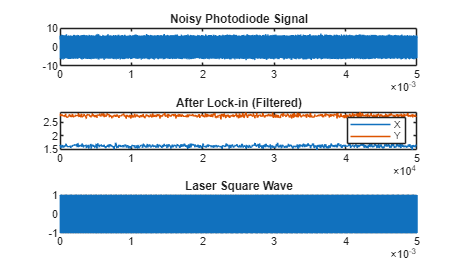


%% Plot
figure;

subplot(3,1,1);
plot(t, signal_noisy);
title('Noisy Photodiode Signal');

subplot(3,1,2);
plot(X);
hold on;
plot(Y);
legend('X','Y');
title('After Lock-in (Filtered)');

subplot(3,1,3);
plot(t, laser);
title('Laser Square Wave');